
gabriels_horn = @(x) 1 ./ x;

x = linspace(1, 40, 4000)

x =     1.0000    1.0098    1.0195    1.0293    1.0390    1.0488    1.0585    1.0683    1.0780    1.0878    1.0975    1.1073    1.1170    1.1268    1.1365    1.1463    1.1560    1.1658    1.1755    1.1853    1.1950    1.2048    1.2146    1.2243    1.2341    1.2438    1.2536    1.2633    1.2731    1.2828    1.2926    1.3023    1.3121    1.3218    1.3316    1.3413    1.3511    1.3608    1.3706    1.3803    1.3901    1.3998    1.4096    1.4194    1.4291    1.4389    1.4486    1.4584    1.4681    1.4779


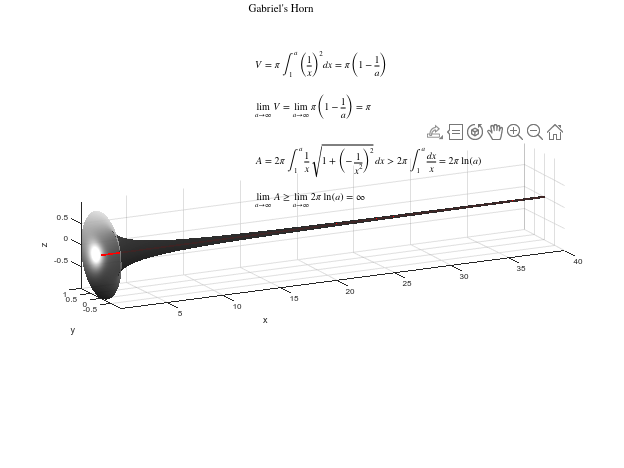

y = gabriels_horn(x);

theta = linspace(0, 2 * pi, 6000);
[X, T] = meshgrid(x, theta);
Y = gabriels_horn(X) .* cos(T);
Z = gabriels_horn(X) .* sin(T);

figure('Position', [200, 100, 1200, 900]);
surf(X, Y, Z, 'EdgeColor', 'none', 'FaceAlpha', 0.9);
hold on;

plot3(x, zeros(size(x)), zeros(size(x)), 'r', 'LineWidth', 2);

xlabel('x');
ylabel('y');
zlabel('z');

colormap('gray');
shading interp;

view(3);
axis tight;
grid on;

dim1 = [0.4 0.7 0.3 0.2];
annotation('textbox',dim1,'String',{'$$V = \pi \int_{1}^{a} \left( \frac{1}{x} \right)^2 dx = \pi \left( 1 - \frac{1}{a} \right)$$', ...
                                   '', ... % Add an empty line for larger gap
                                   '$$\lim_{a \to \infty} V = \lim_{a \to \infty} \pi \left( 1 - \frac{1}{a} \right) = \pi$$'}, ...
           'Interpreter','latex','FontSize',12, 'EdgeColor','none', 'FitBoxToText', 'on');
dim2 = [0.4 0.5 0.3 0.2];
annotation('textbox',dim2,'String',{'$$A = 2\pi \int_{1}^{a} \frac{1}{x} \sqrt{1 + \left( -\frac{1}{x^2} \right)^2} dx > 2\pi \int_{1}^{a} \frac{dx}{x} = 2\pi \ln(a)$$', ...
                                   '', ... % Add an empty line for larger gap
                                   '$$\lim_{a \to \infty} A \geq \lim_{a \to \infty} 2\pi \ln(a) = \infty$$'}, ...
           'Interpreter','latex','FontSize',12, 'EdgeColor','none', 'FitBoxToText', 'on');

dim3 = [0.3 0.9 0.3 0.1];
annotation('textbox',dim3,'String','Gabriel''s Horn', ...
           'Interpreter','latex','FontSize',14, 'EdgeColor','none', 'HorizontalAlignment', 'center');
hold off
daspect([3.5 1 1])
view(-27, 15)
lightangle(-50,0)
lighting('gouraud')